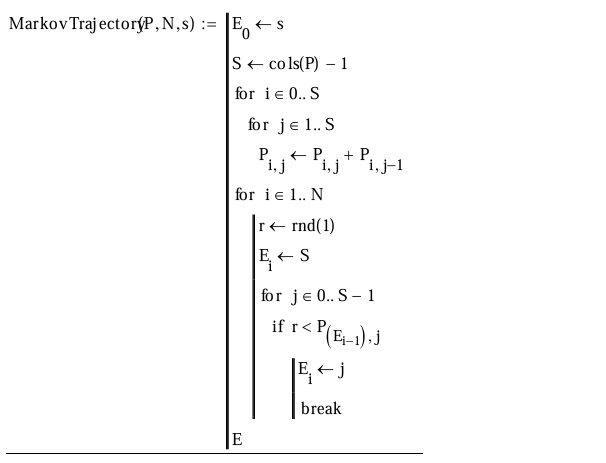

function E = MarkovTrajectory(P, N, s)
    E = zeros(1, N);
    
    E(1) = s;
    
    S = size(P,1);

    for i = 1:S
        for j = 2:S
            P(i, j) = P(i, j) + P(i, j - 1);
        end
    end
    
    for i = 2:N
        r = rand();
        E(i) = S;
        
        for j = 1:S
            if r < P(E(i-1), j)
                E(i) = j;
                break;
            end
        end
    end
end
